## OEMP 1 Work

Load in data, plot flight envelope for "inspiration"

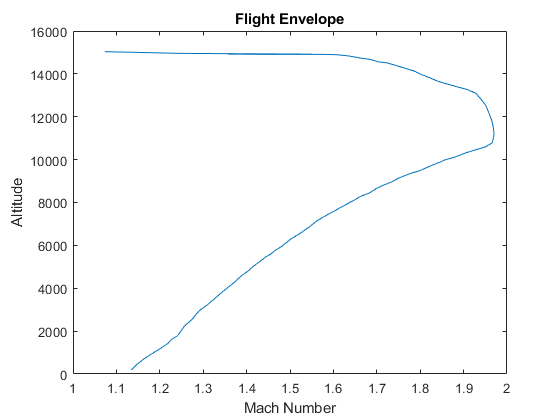

load("OEMP1_data.mat")
% flight_envelope
flight_envelope(1,:) = [];
plot(flight_envelope.mach,flight_envelope.altitude)
title("Flight Envelope")
xlabel("Mach Number")
ylabel("Altitude")

Using the equations: F = A * Q * C_d  and  Q = (1/2) * rho * v^2, plot force versus altitude.

A = (0.3048 * 0.12192) / 2; % m^2
C_d = 1.2; % assumed for a flat plane (simplification)
flight_envelope.Velocity = flight_envelope.mach .* flight_envelope.speed_of_sound;
flight_envelope.Dynamic_Pressure = (1/2) .* flight_envelope.air_density .* (flight_envelope.Velocity).^2;
flight_envelope.Force = A .* flight_envelope.Dynamic_Pressure .* C_d

flight_envelope = 83×7 table
     mach     altitude    speed_of_sound    air_density    Velocity    Dynamic_Pressure    Force 
    ______    ________    ______________    ___________    ________    ________________    ______

    1.1342     196.21         339.54           1.2021       385.09          89132          1987.3
    1.1468     440.87          338.6            1.174       388.32          88514          1973.6
    1.1621     685.77         337.65           1.1464       392.38          88248          1967.6
    1.1773      890.1         336.86           1.1237        396.6          88371          1970.4
    1.2002     1176.3         335.75           1.0925       402.96          88702          1977.8
     1.218     1421.5         334.79          

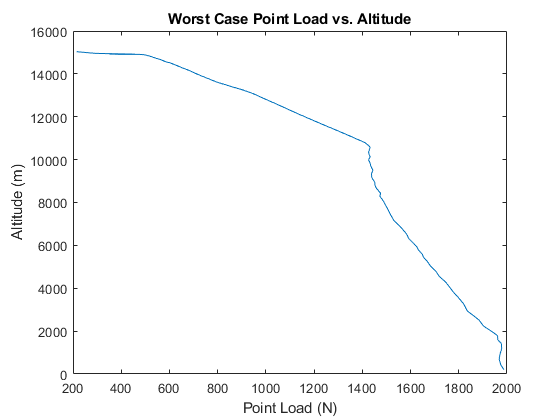

plot(flight_envelope.Force,flight_envelope.altitude)
title("Worst Case Point Load vs. Altitude")
xlabel("Point Load (N)")
ylabel("Altitude (m)")

Given your curve, what is the maximum point load on the turbine blade, and what altitude and aircraft speed does it occur at? Did you need to make any assumptions?

maxForce = max(flight_envelope.Force)

maxForce = 1.9873e+03

% test: minForce = min(flight_envelope.Force)
maxForce_Altitude = flight_envelope.altitude(flight_envelope.Force == maxForce,1)

maxForce_Altitude = 196.2095

maxForce_Velocity = flight_envelope.Velocity(flight_envelope.Force == maxForce,1)

maxForce_Velocity = 385.0902

The maximum force is just under 4 kN, which occurs at an altitude of ~196 m with an aircraft velocity of ~385 m/s. I assumed that air density changed with altitude as provided by the data, and of course the 6 assumptions we made at the beginning. We determined that the F-105 could achieve the speed of sound at an altitude of ~100ft, but reaching the speed of sound at an altitude of zero is unreasonble so we discarded the datapoint. 

Determining the location of the maximum point load